clear all
syms x(t) y(t) T(t)

m=1; r=2; g=1;

eqn1 = m*diff(x(t), 2) == T(t)/r*x(t);
eqn2 = m*diff(y(t), 2) == T(t)/r*y(t) - m*g;
eqn3 = x(t)^2 + y(t)^2 == r^2;
DEs=[eqn1;eqn2]; posnConstraints=eqn3;
vars = [y; x; T];

The unknown functions (just the base functions, not derivatives) are: T(t),x(t),y(t)
Multiple feasible initial conditions found:
Dyt: -1.732051    y: 1.732051    
Dyt: 1.732051    y: -1.732051    

Selecting IC:
Dyt:-1.732051    y:1.732051    
Because it is first.  Use a hint if you want to select a different initial condition.

Initial Conditions:
Y0/YP0:
T: -5.133975 Tt:0.000000
x: 1.000000 xt:3.000000
y: 1.732051 yt:-1.732051
Dxt: 3.000000 Dxtt:-2.566987
Dyt: -1.732051 Dytt:-5.446152


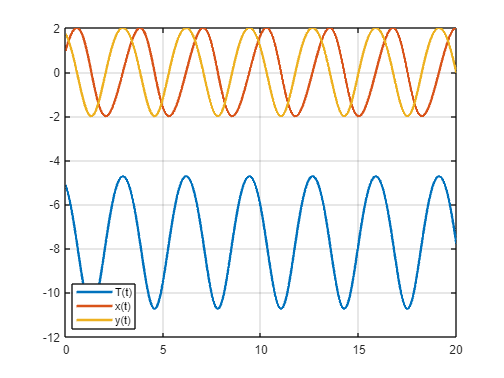

soln=mechanicsAsDAE(DEs,posnConstraints,[],[0,20],{"x==1","Dxt==3"});

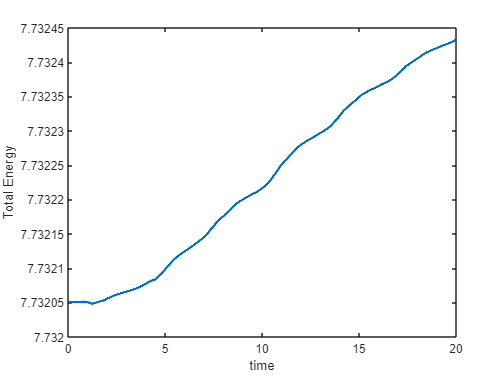


KineticEnergy=1/2*m*(soln.Dxt.^2+soln.Dyt.^2);
PotentialEnergy=m*soln.y*g;
plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')

%Here is a more symbolic approach. 
[DEs,PP]=generateGoveringDEs([eqn1,eqn2],eqn3,[],[y,diff(y)])

The unknown functions are:
T(force)
x
y

Expected Number of State Variables:2
Warning! There are multiple branches for Dytt. This likely means that this dynamical system is piecewise-defined in terms of the state variables.  Arbitrarily selecting the first branch.
Warning! There are multiple branches for Dxt. This likely means that this dynamical system is piecewise-defined in terms of the state variables.  Arbitrarily selecting the first branch.
Warning! There are multiple branches for Dxtt. This likely means that this dynamical system is piecewise-defined in terms of the state variables.  Arbitrarily selecting the first branch.
Warning! There are multiple branches for T. This likely means that this dynamical system is piecewise-defined in terms of the state variables.  Arbitrarily selecting the first branch.
Warning! There are multiple branches for x. This likely means that this dynamical system is piecewise-defined in terms of the state variables.  Arbitrarily selecting the first br

$$DEs = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=\frac{4\,y\left(t\right)\,{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}+{y\left(t\right)}^{4}-8\,{y\left(t\right)}^{2}+16}{4\,\left({y\left(t\right)}^{2}-4\right)}$$

$$PP = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=\frac{y\left(t\right)\,\frac{\partial }{\partial t}y\left(t\right)\,\sigma_{1}}{{y\left(t\right)}^{2}-4}\\ \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=\frac{\sigma_{1}\,\sigma_{2}}{4\,\left({y\left(t\right)}^{2}-4\right)}\\ T\left(t\right)=\frac{\sigma_{2}}{2\,\left({y\left(t\right)}^{2}-4\right)}\\ x\left(t\right)=\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{-\left(y\left(t\right)-2\right)\,\left(y\left(t\right)+2\right)}\\ \sigma_{2}=4\,{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}+{y\left(t\right)}^{3}-4\,y\left(t\right) \end{array}$$

soln=timeStepODESystem(DEs,[y],[y==1,diff(y)==0],[0,20],PP)
plot(soln.t,real(soln.x),soln.t,real(soln.y),soln.t,real(soln.T))